# Intro to MATLAB for Image Analysis - Rodrigo's Notebook

McGill Initiative for Computational Medicine (MiCM) | November 29th, 2023

Rodrigo Migueles Ramirez, Seph Marshall-Burghardt and Teo Lemay

## Instructions

This is meant to be your personal cheat-sheet, your own notebook where you can take notes, try things out and take what you learn today with you. Think of this as notes to your future self, who will only remember parts of this workshop and will potentially need this for their research.

**At the end of today's workshop, you must push (upload) this personalized Live Script to the workshop repo to get your certificate.**

Each section contains topics that you are expected to learn, or have some intuition about.

### Using MATLAB Live Scripts

This Live Script combines Markdown typing with code snippets that you can run and see the result immediately in here. Here are some tips for using Live Scripts:

`**bold** -> ``bold`

`*italics* -> ``italics`

`Ctrl + Shift + L -> Title`

`Ctrl + Shift + 1 -> Header 1`

`Ctrl + Alt + Enter -> New section`

`Alt + Enter -> Toggle between text and code`

`"`" code "`" -> Code line or snippet`

`Select text + Ctrl + K -> Insert hyperlink`

`Ctrl + Up/Down -> Navigate to the beginning of the previous / next section`

## Module 1: Intro to Matlab

### MATLAB Environment

- Workspace

- Variables

- Editor

- Command

What is the first thing you should always do as soon as you open MATLAB? Why does this matter?

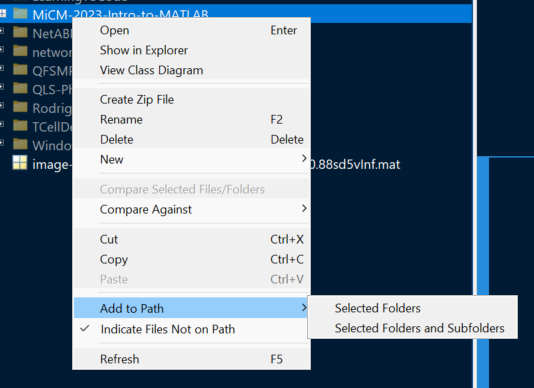

### MATLAB Structure

Types of files and structure:

- Scripts

- Functions

- Live Scripts

Extensions:

- Apps

- Toolboxes

- Runtime environments

- Interface with other languages

### MATLAB Syntax

- Indentation

- Output silencing & `ans`

- Termination

### Running code in MATLAB

- What is the shortkey to run selected lines of code? F9

- Run current section?

- Run the whole file?

- Interrupt code execution?

- How can you see what you have coded before, retrieve it, edit it and run it again?

- How do you erase everything in the workspace?

- How do you hide previous commands from the Command Window?

- How to quickly get help on a selected funciton?

- How to open a file or function? 

- What symbol represents "not"?

- How to comment / uncomment a line? % 

`Ctrl + T / R`

### Programming in MATLAB

- For loops

- While loops

- If/else statements

- Switches

Learn more on [Loops and Conditional Statements](http://web%28fullfile%28docroot%2C%20%27matlab/control-flow.html'))).

### Types of variables in MATLAB

- Matrixes and Arrays

- Numeric types. What is the difference between int and uint? What is a floating-point? What's the difference between integers, single and double? Whats the difference between `true` and 1?

- Characters and Strings, what's the difference?

- Dates and Time

- Categorical Arrays

- Tables

- Timetables

- Structures

- Cell Arrays

- Dictionaries

- Time series

More info on [Data Types](https://www.mathworks.com/help/releases/R2023a/matlab/data-types.html), [Matrices and Arrays](https://www.mathworks.com/help/releases/R2023a/matlab/data-types.html).

[Identifying variable types](http://web%28fullfile%28docroot%2C%20%27matlab/data-type-identification.html'))) and [converting between them](http://web%28fullfile%28docroot%2C%20%27matlab/data-type-conversion.html')))

[Working with Objects in MATLAB](http://web%28fullfile%28docroot%2C%20%27matlab/matlab_oop/working-with-objects-in-matlab.html'))).

[Types of functions in MATLAB](http://web%28fullfile%28docroot%2C%20%27matlab/function-basics.html')))

### Images in MATLAB

#### The image coordinate system in MATLAB

Turn the image upside down. Tip: check out the `ydirection` input type of `axis` [here](http://web%28fullfile%28docroot%2C%20%27matlab/ref/axis.html?s_tid=doc_ta#d124e72734')))

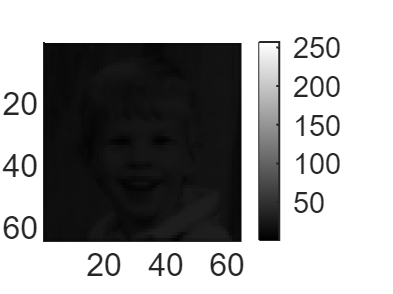

image

Who is this kid and why is he hidden in the default, built-in image? The full story is [here](https://blogs.mathworks.com/steve/2006/10/17/the-story-behind-the-matlab-default-image/). 

#### Image types in MATLAB

peppersImage = imread('peppers.png');
imfinfo('peppers.png')

ans = struct with fields:
                  Filename: 'C:\Program Files\MATLAB\R2023a\toolbox\matlab\imagesci\peppers.png'
               FileModDate: '16-Dec-2002 06:10:58'
                  FileSize: 287677
                    Format: 'png'
             FormatVersion: []
                     Width: 512
                    Height: 384
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '16 

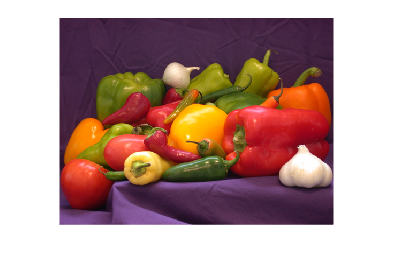

figure; imshow(peppersImage);

size(peppersImage)

ans =    384   512     3


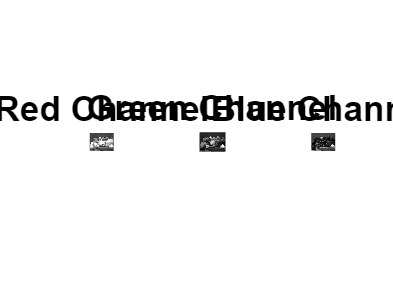

[R, G, B] = imsplit(peppersImage);
figure
subplot(1,3,1)
imshow(R)
title('Red Channel')

subplot(1,3,2)
imshow(G)
title('Green Channel')

subplot(1,3,3)
imshow(B)
title('Blue Channel')

Color representation of each channel:

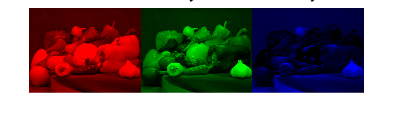

allBlack = zeros(size(peppersImage,1,2), class(peppersImage));
justR = cat(3,R,allBlack,allBlack);
justG = cat(3,allBlack,G,allBlack);
justB = cat(3,allBlack,allBlack,B);

figure
montage({justR,justG,justB},'Size',[1 3], ...
    "BackgroundColor",'k',"BorderSize",0);
title('Color Representation of the Red, Green, and Blue Color Channels');

See more details [here](https://www.mathworks.com/help/releases/R2023a/images/display-separated-color-channels-of-rgb-image.html).

### Colormaps

load('trees.mat'); 
whos map

  Name        Size            Bytes  Class     Attributes

  map       128x3              3072  double              



whos X

  Name        Size              Bytes  Class     Attributes

  X         258x350            722400  double              



X(1:10, 1:10)

ans =    109   117    99   109    88    91    91    87    91    92
   113   113   113   106   113   106   113   106   106   106
   113   113   106   113   113   106   106   106   106    94
   106   106   106   106   106   113   106   106    94   106
   113   106   113   106   106   106   106   106   106   106
   106   106   106   113   106   113   106   106   106   106
   106   113   106   106   113   106   113   106   106   106
   106   106   113   113   113   106   106   106   106   106
   106   106   113   115   118   113   113   106   106   106
   118   121   124   126   124   113   113   113   106   106


max(X, [], 'all')

ans = 128

map

map =          0         0         0
    0.0627    0.0627    0.0314
    0.2902    0.0314         0
         0         0    1.0000
    0.2902    0.0627    0.0627
    0.3882    0.0314    0.0941
    0.4510    0.0627         0
    0.2588    0.1608    0.0627
    0.0941    0.2588    0.0314
    0.2235    0.1922    0.2235


## Module 2: Becoming an autonomous MATLAB coder

### Debugging and troubleshooting

You can diagnose problems in your MATLAB® code files by debugging your code interactively in the Editor and Live Editor or programmatically by using debugging functions in the Command Window.

There are several ways to debug your code:

- Display output by removing semicolons.

- Run the code to a specific line and pause by clicking the Run to Here button.

- Step into functions and scripts while paused by clicking the Step In button.

- Add breakpoints to your file to enable pausing at specific lines when you run your code.

You can find examples for each and more details here.

web(fullfile(docroot, 'matlab/matlab_prog/debugging-process-and-features.html'))

### Error examples and how to fix them:

fixTheWorld

Unrecognized function or variable 'fixTheWorld'.

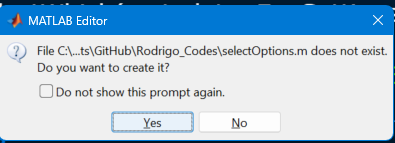

filename = "heartUltrasoundSequenceVideo.dcm";
medImg = medicalImage(filename)

'medicalImage' requires Medical Imaging Toolbox.

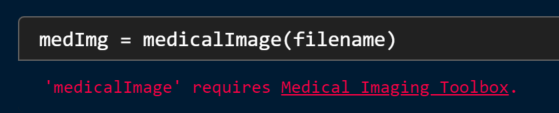

x = ones(3,4,5);
for i = 1:5
    y(:,:,i) = x(:,:,i).*i;
end

img = imread("Images\Dilate Cell Mask.png");

### Learning and documentation

Learning resources:

- [Help Center or Documentation](https://www.mathworks.com/help/releases/R2023a/index.html) - Your first option

- [Online Training](https://www.mathworks.com/learn/training.html): [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) and [MATLAB Fundamentals](https://matlabacademy.mathworks.com/details/mlbe). Guided tutorials to get started.

- [MATLAB Cody](https://www.mathworks.com/matlabcentral/cody/)! Like puzzles and challenges? Train your MATLAB skills and stay sharp!

- MATLAB Central - [File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/). Are you sure it doesn't exist? Maybe someone coded it for you!

- [MATLAB Answers](https://www.mathworks.com/matlabcentral/answers/index/) - Forums can be a double-edge sword!

## Module 3: Image Analysis using MATLAB

### Loading and Visualizing Image Data

The main function to read image data is `imread`:

I = imread('ngc6543a.jpg');
whos I

  Name        Size                 Bytes  Class    Attributes

  I         650x600x3            1170000  uint8              



The image has 3 layers, so we can deduce that it may be coded in an RGB format.

We can get more info on the image using `imfinfo`:

info = imfinfo('ngc6543a.jpg');

The basic way to display an image is using `imshow`:   

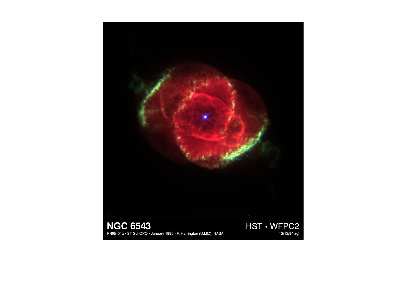

imshow(I);

It can open PNG, JPEG and TIFF files. However, it can only load one "slice" of a TIFF stack (time series or multi channel):

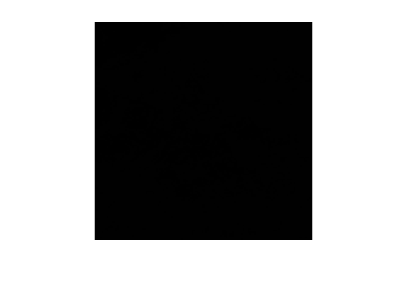

I = imread('210108-3-5-FTractin_reg_205px-short71-100.tif');
imshow(I);

Show the scale:

colorbar

What are the color limits?

clim

ans =            0       10000


Adjust the scale: (replace the values for your best guess, uncomment and update):

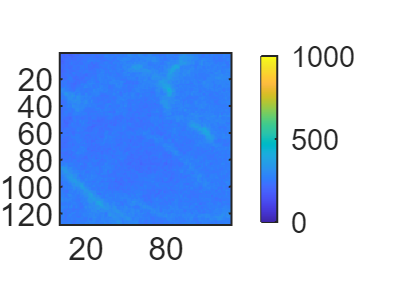

clim([0,1000]);

Hard to guess, right? Instead of `imshow`, you might want to use `imagesc:`

imagesc(I);
clim

ans =    189   432


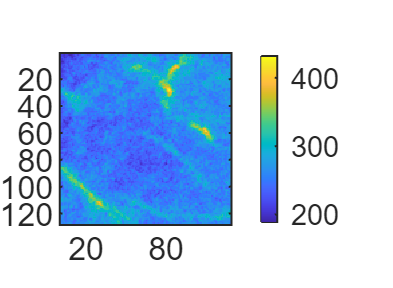

colorbar
axis image;

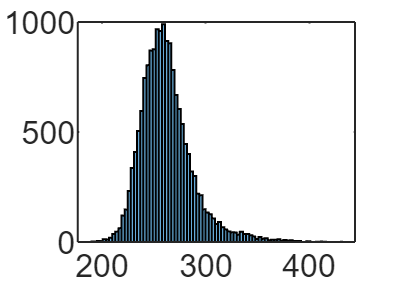

histogram(I);

By default, it loaded only the first frame. We can specify the frame to load:

I = imread('210108-3-5-FTractin_reg_205px-short71-100.tif', 5);
imagesc(I); colorbar; axis image;

Instead, we can use special functions that can read the whole TIFF file. 

stack = readFileToStack('210108-3-5-FTractin_reg_205px-short71-100.tif');
whos stack

  Name         Size                 Bytes  Class     Attributes

  stack      128x128x30            983040  uint16              



   128   128    30

App Stack size = 30


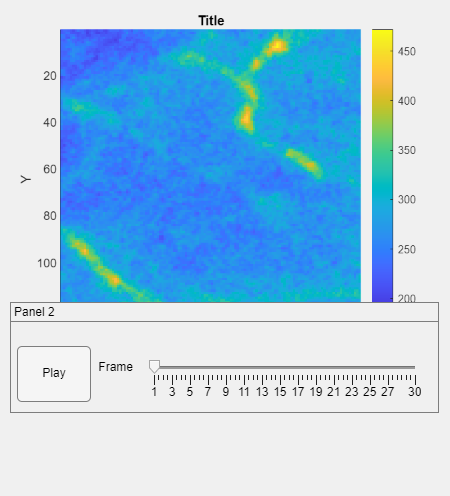

StackViewer(stack);

## Image Analysis Examples and Challenges

#### Image Registration

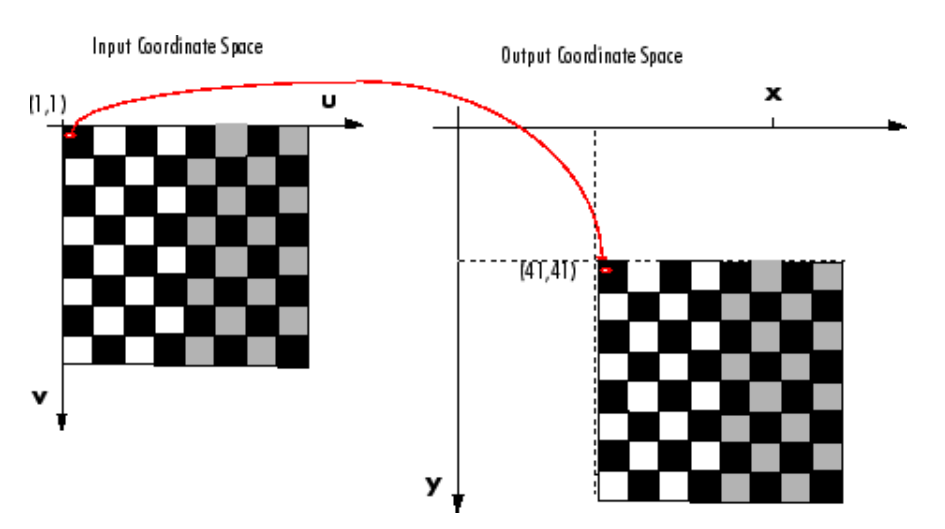

# Find Image Rotation and Scale

This example shows how to align or register two images that differ by a rotation and a scale change. You can calculate the rotation angle and scale factor and transform the distorted image to recover the original image.

## Step 1: Read Image

Read an image into the workspace.

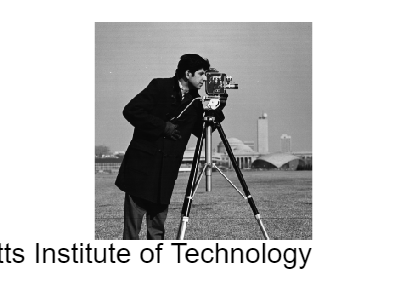

original = imread("cameraman.tif");
imshow(original)
text(size(original,2),size(original,1)+15, ...
    "Image courtesy of Massachusetts Institute of Technology", ...
    FontSize=7,HorizontalAlignment="right")

## Step 2: Resize and Rotate the Image

Create a distorted version of the image by resizing and rotating the image. Note that `imrotate` rotates images in a counterclockwise direction when you specify a positive angle of rotation.

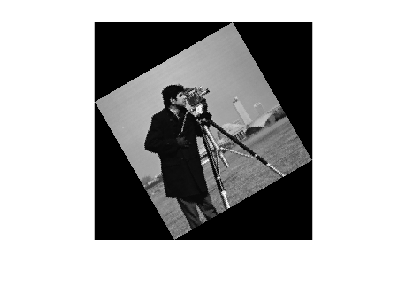

scaleFactor = 0.7;
distorted = imresize(original,scaleFactor);

theta = 30;
distorted = imrotate(distorted,theta);
imshow(distorted)

## Step 3: Select Control Points

This example specifies three pairs of control points.

movingPoints = [128.6 75.4; 151.9 163.9; 192.1 118.6];
fixedPoints = [169.1 73.6; 135.6 199.9; 217.1 171.9];

If you want to pick the control points yourself, then you can use the Control Point Selection Tool. Open this tool by using the `cpselect` function.

## Step 4: Estimate Affine Transformation

Fit a geometric transformation to your control points using the `fitgeotform2d` function. This example fits a similarity transformation because the distortion consists only of rotation and isotropic scaling.

tform = fitgeotform2d(movingPoints,fixedPoints,"similarity")

tform =   simtform2d with properties:

    Dimensionality: 2
             Scale: 1.4257
     RotationAngle: 29.6202
       Translation: [62.7552 -110.3932]
                 R: [2×2 double]
                 A: [3×3 double]


## Step 5: Recover Scale Factor and Rotation Angle

The geometric transformation, `tform`, represents how to transform the moving image to the fixed image. If you want to determine the scale factor and rotation angle that you applied to the fixed image to create the moving image, then use the inverse of the geometric transformation.

tformInv = invert(tform);
tformInv.RotationAngle

ans = -29.6202

The values of the `Scale` property should match the value of `scaleFactor` that you set in **Step 2: Resize and Rotate the Image**.

The value of the `RotationAngle` property should have the same magnitude as the angle `theta` that you set in **Step 2: Resize and Rotate the Image**. However, the angle in `RotationAngle` has the opposite sign as `theta`. The sign is opposite because the `simtform2d` object stores the rotation angle as the amount of rotation from the positive *x-*axis to the positive *y-*axis in intrinsic coordinates. For images, the positive *x* direction points to the right and the positive *y* axis points downward, therefore a positive rotation angle is in the clockwise direction. A positive rotation angle in the clockwise direction corresponds to a negative rotation angle in the counterclockwise direction, and vice versa.

## Step 6: Recover Original Image

Recover the original image by transforming `distorted`, the rotated-and-scaled image, using the geometric transformation `tform` and what you know about the spatial referencing of `original`. Use the `OutputView` name-value argument to specify the resolution and grid size of the resampled output image.

Roriginal = imref2d(size(original));
recovered = imwarp(distorted,tform,OutputView=Roriginal);

Compare `recovered` to `original` by looking at them side-by-side in a montage.

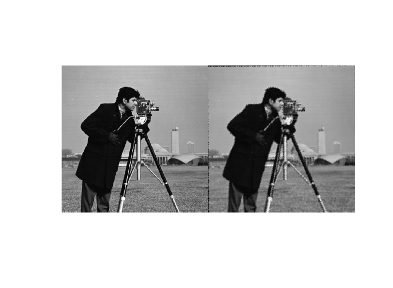

montage({original,recovered})

The recovered (right) image quality does not match the original (left) image because of the distortion and recovery process. In particular, the image shrinking causes information loss. The artifacts around the edges are due to the limited accuracy of the transformation. If you were to pick more points in **Step 3: Select Control Points**, the transformation would be more accurate.

*Copyright 1993-2022 The MathWorks, Inc.*

#### Filtering

What is filtering?

% web(fullfile(docroot, 'images/what-is-image-filtering-in-the-spatial-domain.html'))

Read image and display it. 

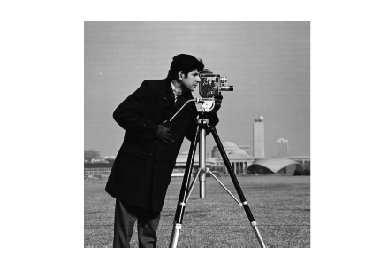

I = imread('cameraman.tif');
imshow(I);

Create a filter and use it to blur the image. Display the blurred image.

This is the kernel or filter that we will use to smudge or blur the image:

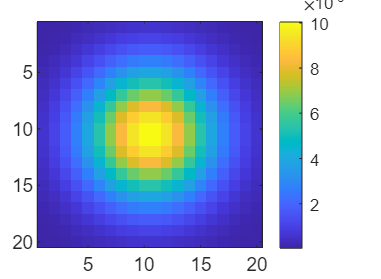

H = fspecial('gaussian',20,4);
imagesc(H); axis image; colorbar;

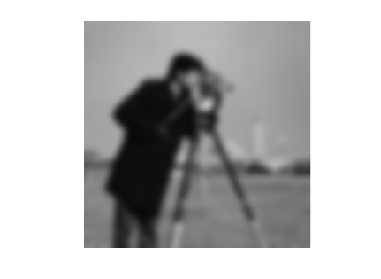

GaussianBlur = imfilter(I,H,'replicate');
imshow(GaussianBlur);

Create a disk filter and use it to blur the image. Display the blurred image.

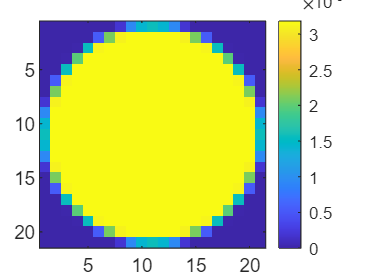

H = fspecial('disk',10);
imagesc(H); axis image; colorbar;

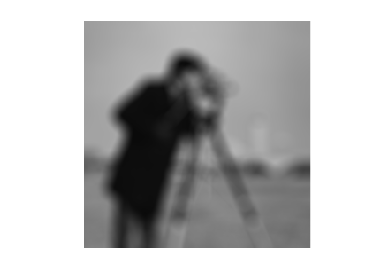

blurred = imfilter(I,H,'replicate'); 
imshow(blurred);

#### Sharpening

Read an image into the workspace and display it.

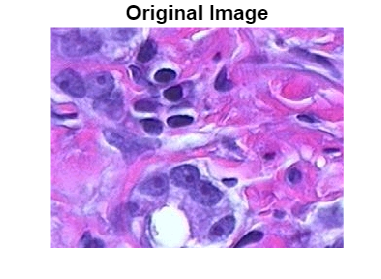

a = imread('hestain.png');
imshow(a)
title('Original Image');

Sharpen the image using the `imsharpen` function and display it.

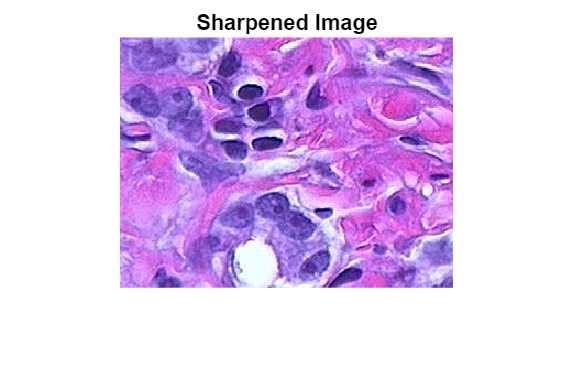

b = imsharpen(a);
figure, imshow(b)
title('Sharpened Image');

The built-in `imsharpen` function uses the *unsharp masking* procedure in which “an image is sharpened by subtracting a blurred (unsharp) version of the image from itself”. We can do something similar directly on the previsous example:

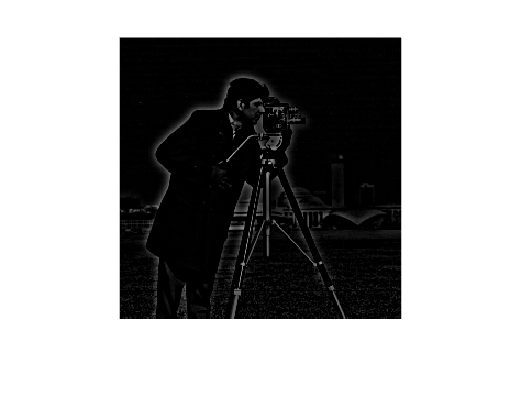

sharpImageGaussian = I - GaussianBlur;
imshow(sharpImageGaussian);

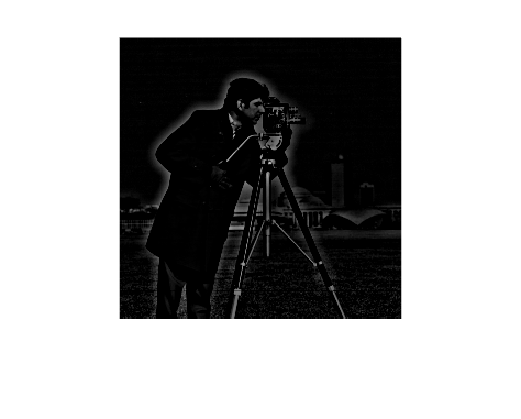

sharpImageDisk = I - blurred;
imshow(sharpImageDisk);

#### Segmentation

Segmentation involves separating an object from the rest of the image.

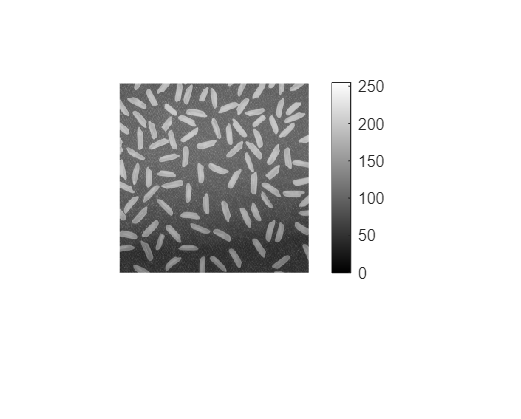

riceImage = imread('rice.png');
imshow(riceImage); colorbar;

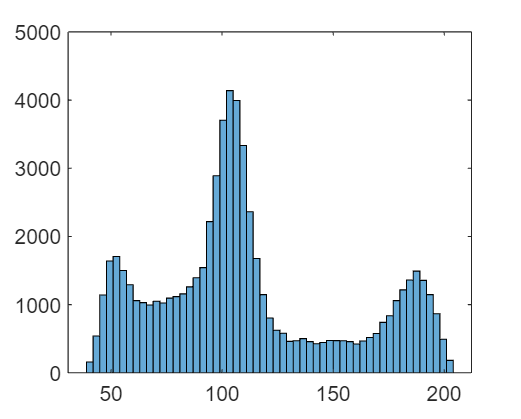

histogram(riceImage);

The three peaks correspond to populations of pixels. Let's try to segment the rice:

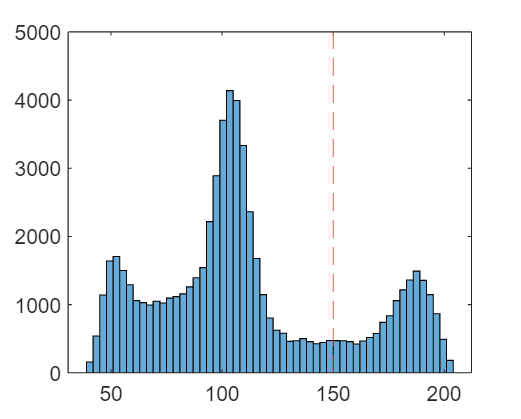

threshold = 150;
histogram(riceImage); 
hold on; % Add something else to the plot
xline(threshold, 'r--');
hold off;

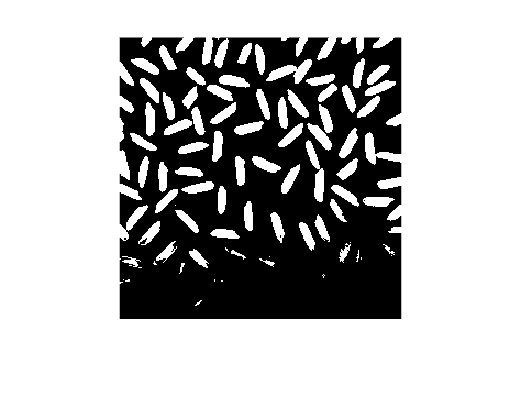

riceMask = riceImage > threshold;
imshow(riceMask);

The background is very heterogeneous. We can try to use the adaptive local threshold algorithm:

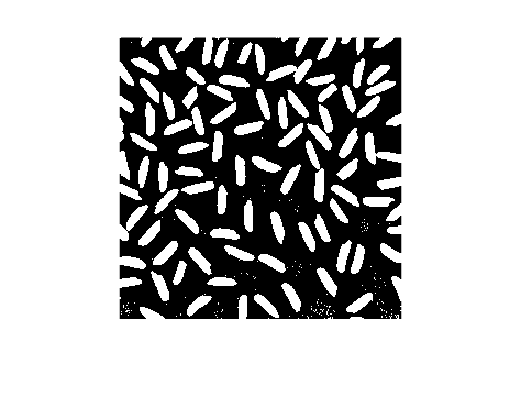

riceMask = imbinarize(riceImage, 'adaptive');
imshow(riceMask);

#### Morphological Operations

Challenge: Read the image "circles.png" and use morphological operations to separate them.

web(fullfile(docroot, 'images/morphological-dilation-and-erosion.html'))

#### Background correction

Now that we know about morphological operations, we can keep working on the rice image. Just as we did in filtering, we can create custom filters or structuring elements using `strel`:

se = strel('disk', 15)

se = strel is a disk shaped structuring element with properties:

      Neighborhood: [29×29 logical]
    Dimensionality: 2


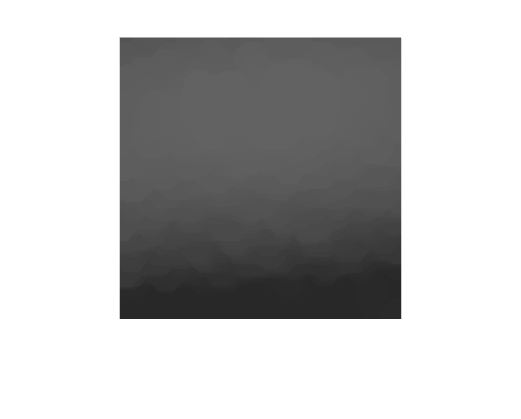

background = imopen(riceImage, se);
imshow(background);

Now we can correct the background by simply subtracting it:

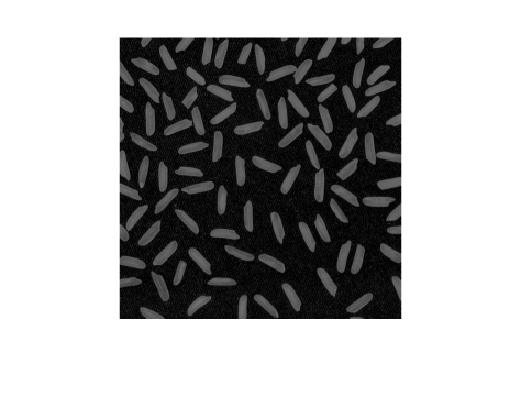

noBGrice = riceImage - background;
imshow(noBGrice);

Now we can segment it:

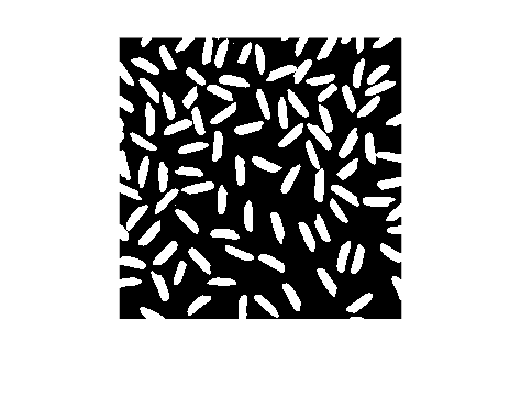

riceMask = imbinarize(noBGrice);
imshow(riceMask);

#### Extract region properties

Let's see how many rice grains we have by finding the number of connected components:

cc4 = bwconncomp(riceMask, 4)

cc4 = struct with fields:
    Connectivity: 4
       ImageSize: [256 256]
      NumObjects: 101
    PixelIdxList: {1×101 cell}


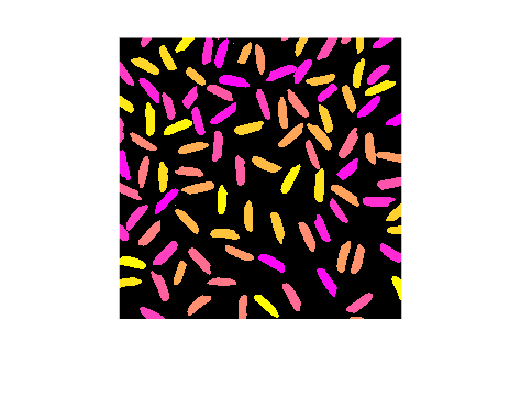

label4 = labelmatrix(cc4);
RGB_label = label2rgb(label4, 'spring', 'k', 'shuffle');
imshow(RGB_label);

With a connectivity of 4, we have 101 rice grains.

cc8 = bwconncomp(riceMask, 8)

cc8 = struct with fields:
    Connectivity: 8
       ImageSize: [256 256]
      NumObjects: 99
    PixelIdxList: {1×99 cell}


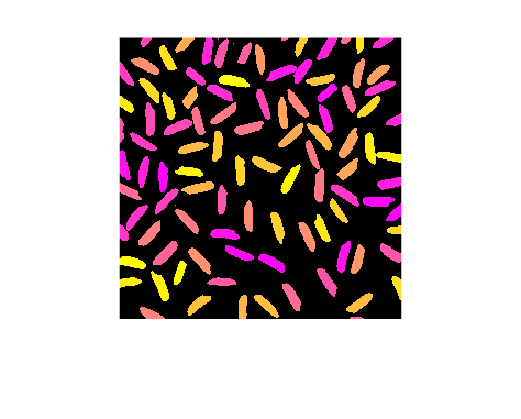

label8 = labelmatrix(cc8);
RGB_label = label2rgb(label8, 'spring', 'k', 'shuffle');
imshow(RGB_label);

But with connectivity 8, we get only 99. 

You might want to take note what connectivity means.

We can now get properties of each object:

rp = regionprops(riceMask)

rp = 99×1 struct array with fields:
    Area
    Centroid
    BoundingBox


Challenge: Use the rice image and extract the major and minor axis, eccentricity and orientation of each grain of rice. Tip: learn more about the region properties function.

You can find more details here:

% openExample('images/NonuniformIlluminationExample');

#### Brightfield cell segmentation

openExample('images/CellSegmentationExample')

[Time-Frequency Analysis](http://web%28fullfile%28docroot%2C%20%27signal/ug/time-frequency-gallery.html?s_tid=doc_srchtitle#mw_a76bed2e-edd0-4662-b2dc-0d45c876060c')))

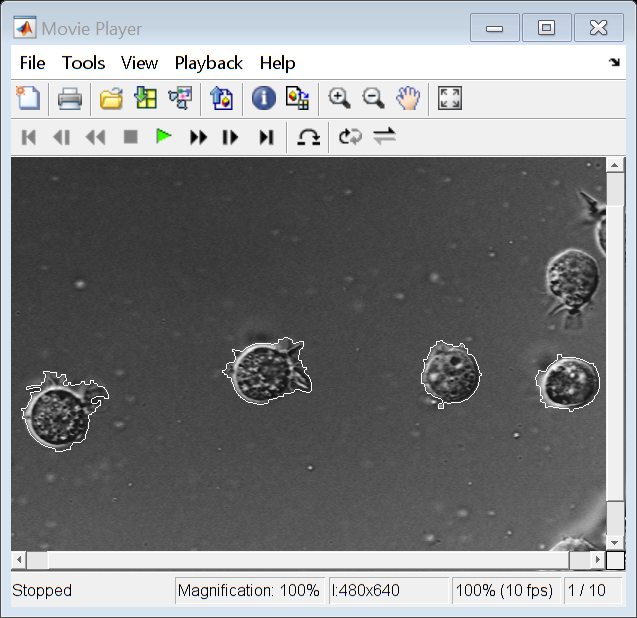

web(fullfile(docroot, 'signal/ug/time-frequency-gallery.html?s_tid=doc_srchtitle#mw_a76bed2e-edd0-4662-b2dc-0d45c876060c'))

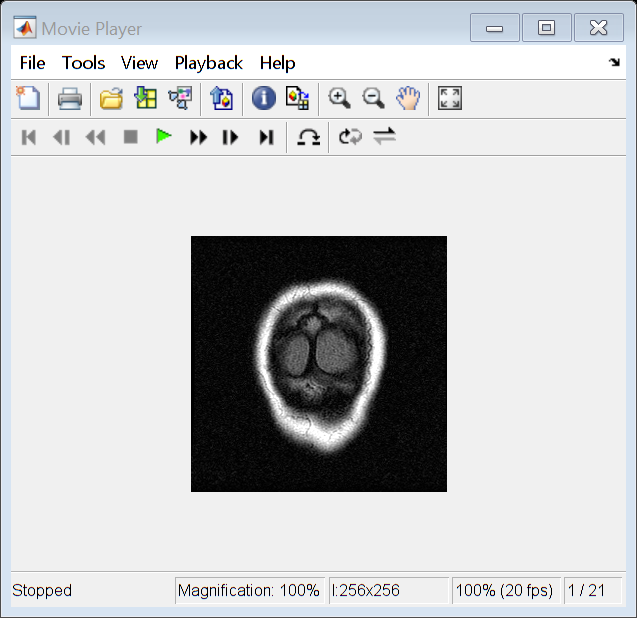

web(fullfile(docroot, 'images/correcting-nonuniform-illumination.html'))
web(fullfile(docroot, 'images/detect-and-count-cell-nuclei-in-wsi-using-blocked-image.html'))

web(fullfile(docroot, 'images/ref/imbinarize.html'))
web(fullfile(docroot, 'signal/ref/pspectrum.html'))

[Morphological Operations](http://web%28fullfile%28docroot%2C%20%27images/morphological-dilation-and-erosion.html'))) - [Find the microchips and remove the circuit lines](http://web%28fullfile%28docroot%2C%20%27images/use-morphological-opening-to-extract-large-image-features.html'))).

Image Filtering: [Example](http://web%28fullfile%28docroot%2C%20%27images/filter-images-using-imfilter.html')))

[Edge Detection](http://web%28fullfile%28docroot%2C%20%27images/ref/edge.html?s_tid=doc_srchtitle%27)))

Immunohistochemistry - [Color-based Segmentation](http://web%28fullfile%28docroot%2C%20%27images/color-based-segmentation-using-k-means-clustering.html')))

[Signal Processing - Sleep EEG](http://web%28fullfile%28docroot%2C%20%27signal/ug/find-periodicity-in-a-categorical-time-series.html?s_tid=doc_srchtitle%27)))

web(fullfile(docroot, 'signal/ug/find-periodicity-in-a-categorical-time-series.html?s_tid=doc_srchtitle'))

[Seeded watershed pear segmentation](http://web%28fullfile%28docroot%2C%20%27images/marker-controlled-watershed-segmentation.html')))

load cellsequence
implay(cellsequence,10)

load mristack

Pearson correlation for colocalization

web(fullfile(docroot, 'stats/corr.html?s_tid=doc_ta#mw_1b19e0d5-7906-4577-a0a5-b20311da7faf'))

Show the correlation using a binned scatter

web(fullfile(docroot, 'matlab/ref/binscatter.html'))

Image Registration

Learn about geometric transformations

web(fullfile(docroot, 'images/matrix-representation-of-geometric-transformations.html'))